# **DEMO_01:**   **Kinematic** analysis of Slider crank mechanism

`Bradley Horton : 25-Feb-2022, bhorton@mathworks.com`

Consider the slider crank mechanism shown in **Figure 1** below. 

**TOLD:**

- Crank AB rotates with a CONSTANT angular velocity of $\omega_{\textrm{AB}} =150\;\frac{\textrm{rad}}{\sec }$

**FIND:**

- The velocity of point P when $\theta =30\;\textrm{degrees}$

**Figure 1**:  the system to be analysed

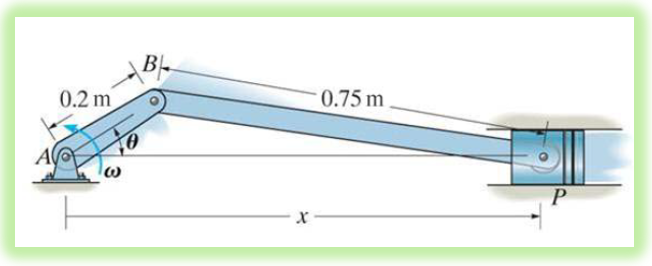

Let's define some MATLAB variables that characterise the system shown in **Figure 1 **and** Figure 2:**

theta_rad  = deg2rad(30);  % (rad)
omega_AB   = 150;          % (rad/sec)
L_AB       = 0.2;          % (m) 
L_BP       = 0.75;         % (m)

## TASK_01:    Establish some useful relationships from the system's geometry

**Figure 2**:  The system geometry

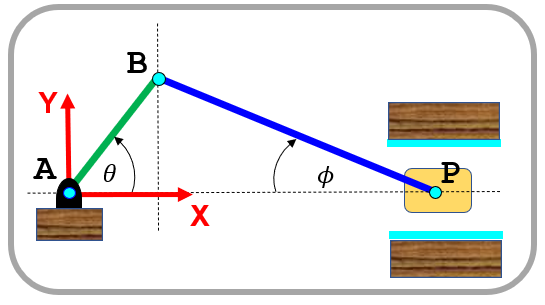

From the mechanism's geometry we see that:

- $L_{\textrm{AB}} \ldotp \sin \left(\theta \left(t\right)\right)\;\;=\;\;L_{\textrm{BP}} \ldotp \sin \left(\phi \left(t\right)\right)$    ................    **EQ_1**

So differentiating BOTH sides of **EQ_1** w.r.t.  time we get

- $L_{\textrm{AB}} \ldotp \frac{d\theta }{\textrm{dt}}\ldotp \cos \left(\theta \left(t\right)\right)=L_{\textrm{BP}} \ldotp \frac{d\phi }{\textrm{dt}}\ldotp \cos \left(\phi \left(t\right)\right)$   ................    **EQ_2**

So:

- $\frac{d\phi }{\mathrm{dt}}\;\;=\;\;\frac{L_{\mathrm{AB}} }{L_{\mathrm{BP}} }\ldotp \frac{d\theta }{\mathrm{dt}}\ldotp \frac{\cos \left(\theta \left(t\right)\right)}{\cos \left(\phi \left(t\right)\right)}$  .............  **EQ_3**

## TASK_02:    Derive $\frac{{\textrm{dx}}_P }{\textrm{dt}}$

From Figure 2 we see that

- $x_P \;\;=\;\;L_{\textrm{AB}} \ldotp \cos \left(\theta \left(t\right)\right)\;\;+\;\;L_{\textrm{BP}} \ldotp \cos \left(\phi \left(t\right)\right)$.............  **EQ_4**

So differentiating BOTH sides w.r.t.  time we get

- $\frac{{\textrm{dx}}_P }{\textrm{dt}}\;\;=\;\;-L_{\textrm{AB}} \ldotp \frac{d\theta }{\textrm{dt}}\ldotp \sin \left(\theta \left(t\right)\right)\;\;+\;\;-L_{\textrm{BP}} \ldotp \frac{d\phi }{\textrm{dt}}\ldotp \sin \left(\phi \left(t\right)\right)$.............  **EQ_5**

And substituting **EQ_3** into **EQ_5**  we get

- $\frac{{\textrm{dx}}_P }{\textrm{dt}}\;\;=\;\;-L_{\textrm{AB}} \ldotp \frac{d\theta }{\textrm{dt}}\ldotp \sin \left(\theta \left(t\right)\right)\;\;+\;\;-L_{\textrm{BP}} \ldotp \frac{L_{\textrm{AB}} }{L_{\textrm{BP}} }\ldotp \frac{d\theta }{\textrm{dt}}\ldotp \frac{\cos \left(\theta \left(t\right)\right)}{\cos \left(\phi \left(t\right)\right)}\ldotp \sin \left(\phi \left(t\right)\right)$.............  **EQ_5**

And if we use the symbol $\omega_{\textrm{AB}} =\frac{d\theta }{\textrm{dt}}$ then **EQ_5** becomes:

- $\frac{{\textrm{dx}}_P }{\textrm{dt}}\;\;=\;\;\omega_{\textrm{AB}} \;\ldotp \;\left\lbrack -L_{\textrm{AB}} \ldotp \ldotp \sin \left(\theta \left(t\right)\right)\;\;+\;\;-L_{\textrm{BP}} \ldotp \frac{L_{\textrm{AB}} }{L_{\textrm{BP}} }\ldotp \frac{\cos \left(\theta \left(t\right)\right)}{\cos \left(\phi \left(t\right)\right)}\ldotp \sin \left(\phi \left(t\right)\right)\right\rbrack$.............  **EQ_6**

- $\frac{{\textrm{dx}}_P }{\textrm{dt}}\;\;=\;\;\omega_{\textrm{AB}} \;\ldotp \;\left\lbrack -L_{\textrm{AB}} \ldotp \ldotp \sin \left(\theta \left(t\right)\right)\;\;+\;-L_{\textrm{AB}} \ldotp \frac{\cos \left(\theta \left(t\right)\right)}{\cos \left(\phi \left(t\right)\right)}\ldotp \sin \left(\phi \left(t\right)\right)\right\rbrack$.............  **EQ_7**

## TASK_03:    Compute $\frac{{\textrm{dx}}_P }{\textrm{dt}}$

Now let's implement these computations in MATLAB.  Recall the following:

- $L_{\textrm{AB}} \ldotp \sin \left(\theta \left(t\right)\right)\;\;=\;\;L_{\textrm{BP}} \ldotp \sin \left(\phi \left(t\right)\right)$    ................    **EQ_1**

- $\frac{{\textrm{dx}}_P }{\textrm{dt}}\;\;=\;\;\omega_{\textrm{AB}} \;\ldotp \;\left\lbrack -L_{\textrm{AB}} \ldotp \ldotp \sin \left(\theta \left(t\right)\right)\;\;+\;-L_{\textrm{AB}} \ldotp \frac{\cos \left(\theta \left(t\right)\right)}{\cos \left(\phi \left(t\right)\right)}\ldotp \sin \left(\phi \left(t\right)\right)\right\rbrack$.............  **EQ_7**

sine_phi =  (L_AB/L_BP) * sin(theta_rad)  % using EQ_1

sine_phi = 0.1333

phi_rad  = asin(sine_phi);                % (rad)

my_sol_vel_P    = omega_AB * (  -L_AB*sin(theta_rad)  +  -L_AB*cos(theta_rad)*sin(phi_rad)/cos(phi_rad) ) % (m/s)

my_sol_vel_P = -18.4953

## TASK_04:    define $\omega_{\textrm{BP}}$

## 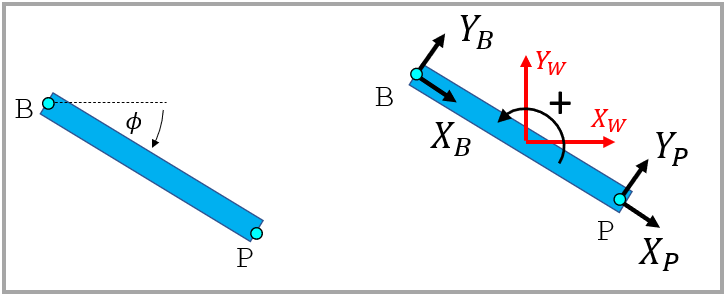

The angular velocity of the connecting rod BP is:

- 
$$\omega_{\textrm{BP}} \;\;=\;\;\;-1\ldotp \frac{d\phi }{\textrm{dt}}$$


## Summarise our results:

my_results.theta_deg        = rad2deg(theta_rad);
my_results.omega_AB_radpsec = omega_AB;
my_results.phi_deg          = rad2deg(phi_rad);
my_results.omega_BP_radpsec = -1 * (L_AB/L_BP)*omega_AB*cos(theta_rad)/cos(phi_rad);
my_results.p_pos            = L_AB*cos(theta_rad)  +  L_BP*cos(phi_rad);
my_results.p_vel            = my_sol_vel_P;


my_results

my_results = struct with fields:
           theta_deg: 30.0000
    omega_AB_radpsec: 150
             phi_deg: 7.6623
    omega_BP_radpsec: -34.9531
               p_pos: 0.9165
               p_vel: -18.4953


##  Compare against Simulink

Let's check our results by exploring a Simulink model.  Click on the button below to open the model:

  open_system("bh_model_crank_kinematics.slx")

When the Simulink model appears, click the Run button - this will simulate the model for 0.1 seconds

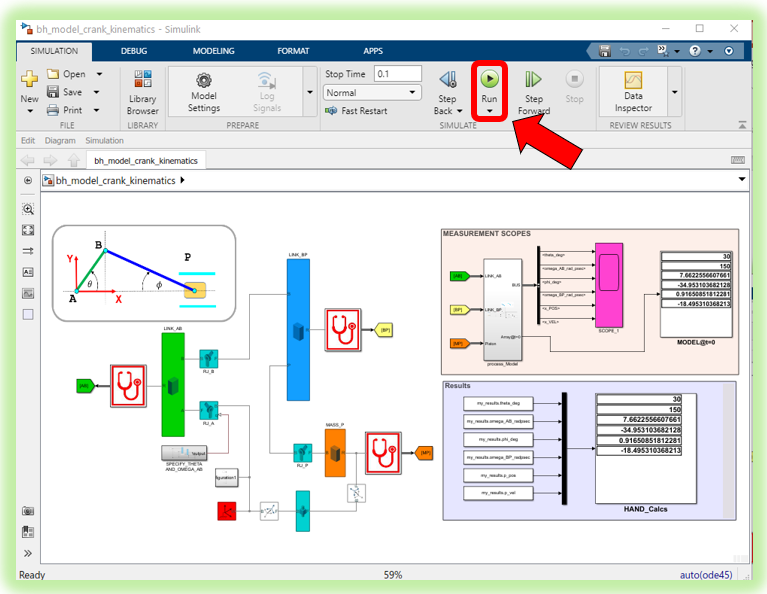

 

- Explore the PINK SCOPE block and inspect the time series of the various angles and positions .

- when you zoom in around the $t=0\;\textrm{seconds}$ region in the SCOPES, do you see values for $v_P$ and $\omega_{\textrm{BP}}$ that are similar to your hand calculations ?

When you run the simulation you also get to see the mechanism animate for the 0.1 seconds of the simulation.